## Chapter 1 Level 1  Solution transfer to Level 4

clear
initUtility
set_sprites
set_rules
P = readtable('data/participants.csv');
h = size(P, 1);
P = sortrows(P, 'SubNo');

levelConfigs = importConfigMap('data/map_config');
cloud_cluster = levelConfigs(2).spriteClusters(Sprites('Cloud'));
[y, x] = find(cloud_cluster);
bnd_upper = max(y);
bnd_lower = min(y);
bnd_left = min(x);
bnd_right = max(x);

detour = zeros(64, 2, 'logical');

for i = 1:h
    tic
    filename = [ 'data/player_map_analyzed/map_logic_', num2str(P.Date(i)), '_', P.Name{i}, '.mat' ];
    load(filename);

    chp = 1;
    lvls = [1, 4];
    for j = 1:2
        lvl = lvls(j);
        logicalArray = [mapHistory(:).Chapter] == chp - 1 ...
                                & [mapHistory(:).Level] == lvl - 1 ;
        levelHistory = mapHistory(logicalArray);
        wins = arrayfun(@(x) checkResultForReplay(x, 'Win'), levelHistory);
        first_win = find(wins, 1, 'first');
        start = max(first_win - 8, 1);
        for t = start:first_win
            [y, x] = find(levelHistory(t).propertyClusters(Rules('You')));
            if any(y > bnd_upper) || any(y < bnd_lower) || any(x < bnd_left) || any(x > bnd_right)
                detour(i, j) = true;
                break;
            end
        end
    end
    toc
end

Elapsed time is 7.047454 seconds.
Elapsed time is 6.447364 seconds.
Elapsed time is 8.124573 seconds.
Elapsed time is 9.120267 seconds.
Elapsed time is 10.678720 seconds.
Elapsed time is 6.220791 seconds.
Elapsed time is 8.809960 seconds.
Elapsed time is 9.640124 seconds.
Elapsed time is 8.602968 seconds.
Elapsed time is 12.018773 seconds.
Elapsed time is 5.239970 seconds.
Elapsed time is 10.157515 seconds.
Elapsed time is 5.686609 seconds.
Elapsed time is 6.589352 seconds.
Elapsed time is 13.398677 seconds.
Elapsed time is 7.476227 seconds.
Elapsed time is 4.912502 seconds.
Elapsed time is 14.134898 seconds.
Elapsed time is 6.006546 seconds.
Elapsed time is 7.551522 seconds.
Elapsed time is 10.591864 seconds.
Elapsed time is 16.371724 seconds.
Elapsed time is 10.296741 seconds.
Elapsed time is 7.028451 seconds.
Elapsed time is 6.050509 seconds.
Elapsed time is 7.275562 seconds.
Elapsed time is 5.852341 seconds.
Elapsed time is 5.895191 seconds.
Elapsed time is 8.321567 seconds.
Elapse

## Chapter 2 Level 4  Solution transfer to Level 5

importData
LvlNo = [4, 5, 1];
VerId = {[0, 0, 0, 0], [0 0 0 1 1], [0 1 1]};
behaviorSummary = table('Size', [64, 5], 'VariableTypes', {'double', 'double', 'double', 'double', 'double'},...
                                'VariableNames', {'SubNo', 'pushText', 'pushTextAsExtensionButFail', 'lvl4Type', 'lvl5Type'});

chp = 2;
lvl = 5;
subCount = 0;
for ver = 0:1 %0:VerId{chp}(lvl)
    filedir = sprintf('data/level_player_map_history/chp_%d_lvl_%d_ver_%d.mat', chp, lvl, ver);
    load(filedir)
    if chp < 3
        logicalArray = [levelConfigs(:).chapter] == chp ...
            & [levelConfigs(:).level] == lvl ...
            & [levelConfigs(:).version] == ver;
    else
        logicalArray = [levelConfigs(:).chapter] == chp;
    end
    height = levelConfigs(logicalArray).size.y;
    allSub = [levelHistory(:).SubNo];
    subList = unique(allSub);
    n_sub = length(subList);
    for i = 1:n_sub
        s = subList(i);
        actionLabels = [levelHistory(allSub == s).actionLabel];
        pushText = [actionLabels(:).directlyPushText];
        destroyed = [actionLabels(:).areYouDestroyed];
        lvl_4_type = P.c4(P.SubNo == s); % uncorrelated with lvl 4 or lvl 5 type
        subCount = subCount + 1;
        behaviorSummary(subCount, :) = {s, sum(pushText), sum(destroyed & pushText), lvl_4_type, ver};
    end
end

behaviorSummary = sortrows(behaviorSummary, 'SubNo');
behaviorSummary.lastLevelTime2Win = T.Time2Win(T.Chapter == 2 & T.Level == 4);
behaviorSummary.lastLevelSteps2Win = T.Steps2Win(T.Chapter == 2 & T.Level == 4);
behaviorSummary.preTestTime2Win = T.Time2Win(T.Chapter == 2 & T.Level == 1);
behaviorSummary.preTestSteps2Win = T.Steps2Win(T.Chapter == 2 & T.Level == 1);
behaviorSummary.thisLevelTime2Win = T.Time2Win(T.Chapter == 2 & T.Level == 5);
behaviorSummary.thisLevelTime2Initiate = T.Time2Initiate(T.Chapter == 2 & T.Level == 5);
behaviorSummary.thisLevelSteps2Win = T.Steps2Win(T.Chapter == 2 & T.Level == 5);
behaviorSummary.baselineTime2Win = T.Time2Win(T.Chapter == 2 & T.Level == 3);
behaviorSummary.baselineSteps2Win = T.Steps2Win(T.Chapter == 2 & T.Level == 3);

transferred_chp2 = behaviorSummary.pushTextAsExtensionButFail > 0;
sum(transferred_chp2)

ans = 19

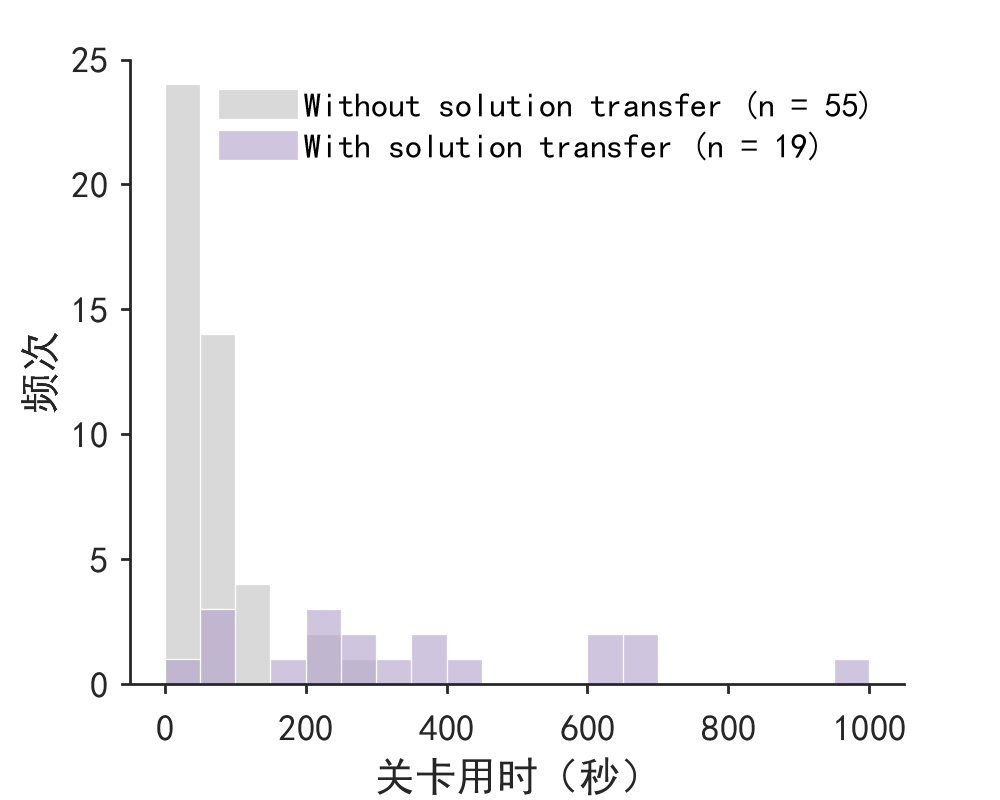

t_nontranster = behaviorSummary.thisLevelTime2Win(~transferred_chp2);
t_transfer    = behaviorSummary.thisLevelTime2Win(transferred_chp2);

figure('Position', [100 100 500 400])
h1 = histogram(t_nontranster,'FaceColor', [0.75 0.75 0.75], 'EdgeColor', [1 1 1]); hold on
h2 = histogram(t_transfer, 'FaceColor', [176 159 202]./255, 'EdgeColor', [1 1 1]);

h1.BinWidth = 50;
h2.BinWidth = 50;

set_figure_prop
legend({'Without solution transfer (n = 55)', 'With solution transfer (n = 19)'}, ...
    'Location',"northeast")
xlabel('关卡用时（秒）')
ylabel('频次')

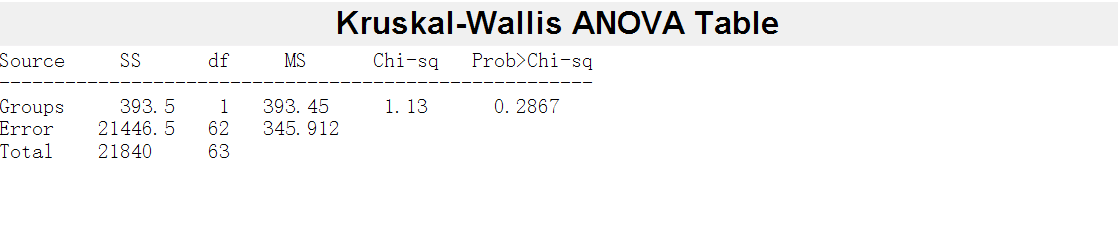

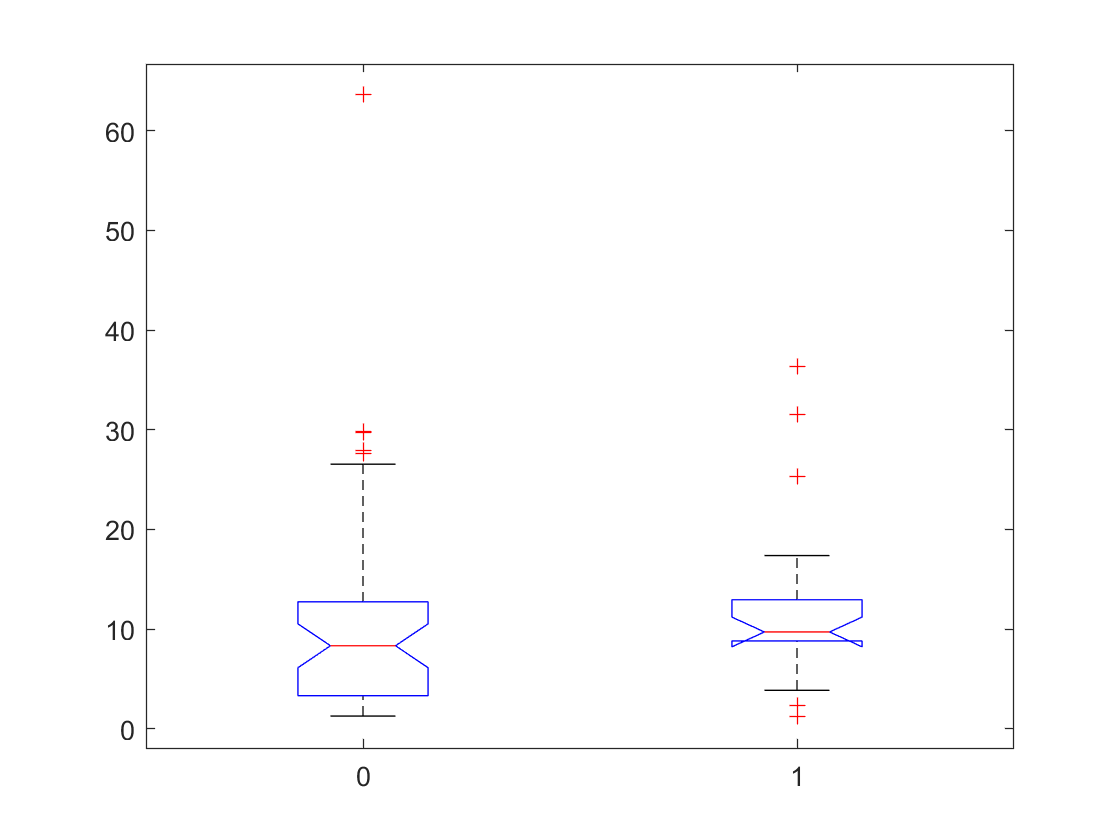

p = 0.2867

p = kruskalwallis(behaviorSummary.thisLevelTime2Initiate,transferred_chp2)

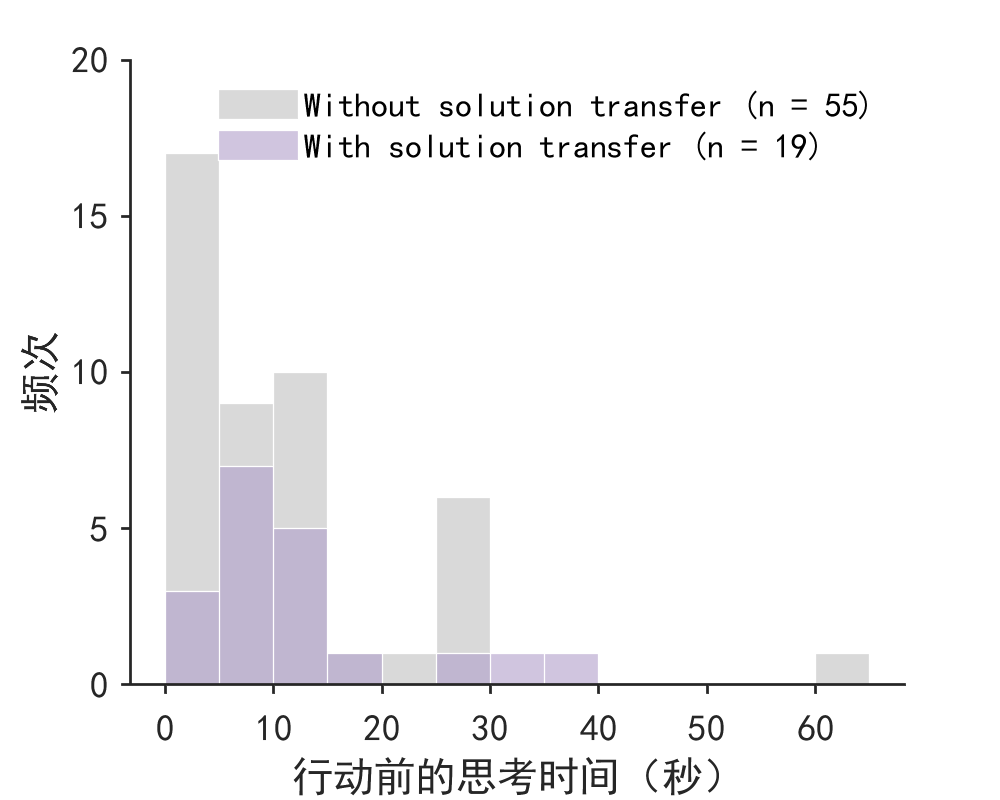

t_nontranster = behaviorSummary.thisLevelTime2Initiate(~transferred_chp2);
t_transfer    = behaviorSummary.thisLevelTime2Initiate(transferred_chp2);

figure('Position', [100 100 500 400])
h1 = histogram(t_nontranster,'FaceColor', [0.75 0.75 0.75], 'EdgeColor', [1 1 1]); hold on
h2 = histogram(t_transfer, 'FaceColor', [176 159 202]./255, 'EdgeColor', [1 1 1]);

h1.BinWidth = 5;
h2.BinWidth = 5;

set_figure_prop
legend({'Without solution transfer (n = 55)', 'With solution transfer (n = 19)'}, ...
    'Location',"northeast")
xlabel('行动前的思考时间（秒）')
ylabel('频次')

behaviorSummary.z_lastLevelTime2Win = zscore(behaviorSummary.lastLevelTime2Win);
behaviorSummary.z_thisLevelTime2Win = zscore(behaviorSummary.thisLevelTime2Win);
behaviorSummary.z_pushTextAsExtensionButFail = zscore(behaviorSummary.pushTextAsExtensionButFail);
behaviorSummary.z_thisLevelTime2Initiate = zscore(behaviorSummary.thisLevelTime2Initiate);
fitlme(behaviorSummary, 'z_thisLevelTime2Initiate ~ z_lastLevelTime2Win * z_pushTextAsExtensionButFail')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    z_thisLevelTime2Initiate ~ 1 + z_lastLevelTime2Win*z_pushTextAsExtensionButFail

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    189.51    200.31    -89.757          179.51  

Fixed effects coefficients (95% CIs):
    Name                                                        Estimate      SE         tStat        DF    pValue     Lower       Upper  
    {'(Intercept)'                                     }        -0.0016294    0.12337    -0.013207    60    0.98951    -0.24841    0.24515
    {'z_lastLevelTime2Win'                             }           0.11967    0.12756      0.93816    60    0.35192    -0.13548    0.37482
    {'z

fitlme(behaviorSummary, 'z_thisLevelTime2Win ~ z_lastLevelTime2Win * z_pushTextAsExtensionButFail')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    z_thisLevelTime2Win ~ 1 + z_lastLevelTime2Win*z_pushTextAsExtensionButFail

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    136.24    147.03    -63.119          126.24  

Fixed effects coefficients (95% CIs):
    Name                                                        Estimate      SE          tStat        DF    pValue        Lower        Upper  
    {'(Intercept)'                                     }        -0.0037164    0.081367    -0.045674    60       0.96372     -0.16648    0.15904
    {'z_lastLevelTime2Win'                             }          0.078427    0.084129      0.93222    60       0.35496    -0.089856    0.246

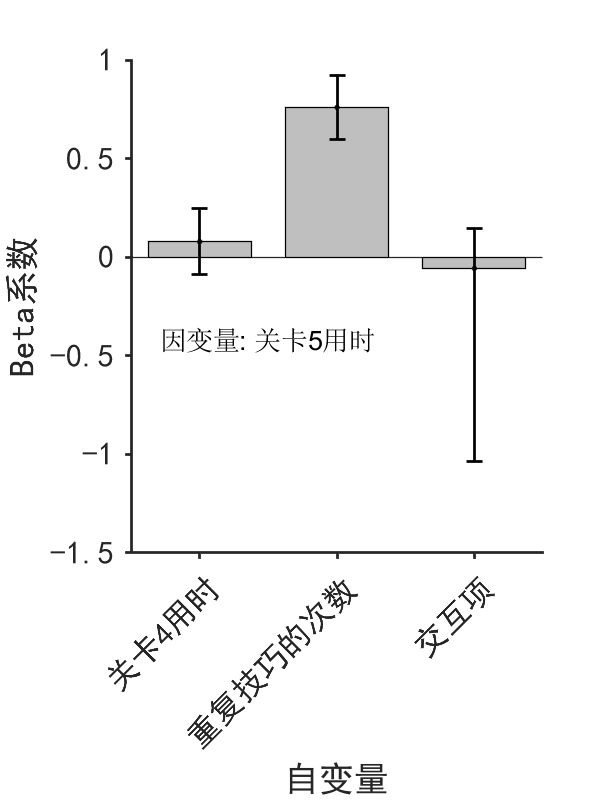

m = [0.078427 0.75945 -0.057116];
neg = [-0.089856 0.59509 0.92381];
pos = [0.24671 0.92381 0.14768];

figure('Position', [0 0 300 400])

b = bar(m, 0.75); hold on
b.FaceColor = [0.75 0.75 0.75];
f = @(a)bsxfun(@plus,cat(1,a{:,1}),cat(1,a{:,2})).';
errorbar(f(get(b,{'xoffset','xdata'})),m,m - neg, pos - m,'.','Color','k','linewidth',1)
set_figure_prop
xlabel('自变量')
xlim([0.5 3.5])
xticklabels({'关卡4用时' '重复技巧的次数' '交互项'})
xtickangle(45)
set(gca, 'FontSize', 12)
ylabel('Beta系数')
legend off

text(1.5,-0.5,'因变量: 关卡5用时','HorizontalAlignment','center',...
    'VerticalAlignment','bottom')